# movie for FM depth

close all
clear variables

figure;
set(gcf, 'position', [681   700   960   410])
testFo = 120;
snrList = 70:-1:0;
fmCent = 25;
outDirName = "/Volumes/Macintosh HD/Users/kawahara/";
mkdir(outDirName + "movie6");

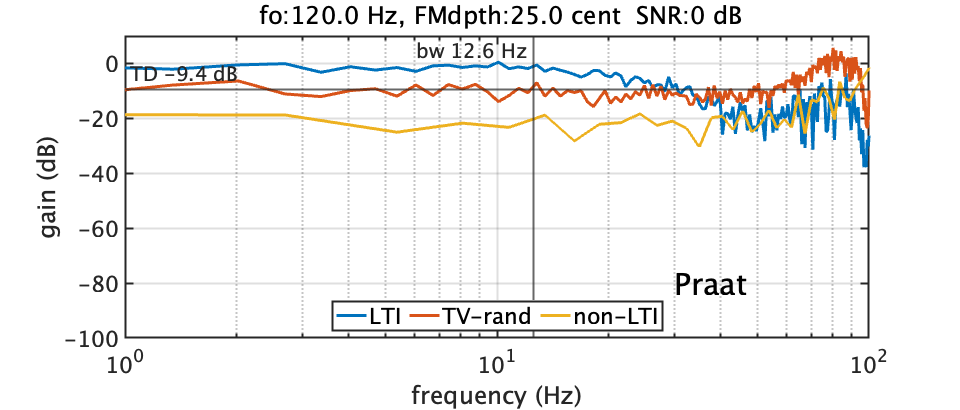

/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997
/sw/bin/init.csh: No such file or directory.
1997


%try
for ii = 1:length(snrList)
    snr = snrList(ii);
    fl = 80;
    fh = 400;
    nOct = 48;
    %outDirName = "/Volumes/SSPL-UT/testCAPRICEP/";
    output = fmTransfTestPeriodicRevSNR(testFo, fmCent, @pitchPraatRevDef,'pink', snr);
    %handle1 = figure;
    %titleStr = output.testCondStr.titleStr;
    titleStr = {'Praat'};
    %foList = dataOut.fcList;
    fxSeg = output.fxSeg;
    fxlResp = output.fxlResp;
    fxSeg(1) = fxSeg(2)/1000000000;
    respLTI = 20*log10(abs(mean(output.lRespInd,2)));
    respLTI(isnan(respLTI)) = 0;
    respTVI = 10*log10(output.varTVL);
    respTVI(isnan(respTVI)) =0;
    respNLTI = 10*log10(output.varNLTI);
    respNLTI(isnan(respNLTI)) = 0;
    semilogx(fxlResp, respLTI, 'linewidth', 3);
    hold all;
    semilogx(fxlResp, respTVI, 'linewidth', 3);
    semilogx(fxSeg, respNLTI, 'linewidth', 3);
    grid on;
    set(gca, 'fontsize', 22, 'linewidth', 2)
    axis([1 100 -100 10])
    title(" fo:" + num2str(testFo, '%7.1f') + " Hz, FMdpth:" ...
        + num2str(fmCent, '%7.1f') + " cent  SNR:" + num2str(snr) + " dB");
    if ~isnan(output.bandWidth)
        xline(output.bandWidth,'-',['bw ' num2str(output.bandWidth,'%4.1f') ' Hz'], ...
            'FontSize',20,'LineWidth', 2,'LabelOrientation',...
            'horizontal','LabelVerticalAlignment','top','LabelHorizontalAlignment','left')
    end
    if ~isnan(output.avTotalErr)
        yline(output.avTotalErr, '-', ['TD ' num2str(output.avTotalErr,'%5.1f') ' dB'],...
            'LabelHorizontalAlignment','left','FontSize',20,'LineWidth', 2)
    end
    xlabel('frequency (Hz)')
    ylabel('gain (dB)')
    text(30, -80, titleStr, 'FontSize', 30)
    legend('LTI', 'TV-rand', 'non-LTI', 'location', 'south','Orientation','horizontal', 'fontsize', 22);
    drawnow
    hold off
    outname = outDirName + "movie6/" + "pic" + num2str(ii,'%04.0f') + ".png";
    print('-dpng','-r100',outname);
end

%catch
%keyboard
%end

